# HSFP Probabilities Test File

**Author: Nina Matthews**

**Project: Masters Dissertation - Blending Mean-Variance and Hierarchical Risk Parity using Time- and Market-Conditioned Flexible Probabilities**

**Last edit: 11/07/2023**

**Supervisor: A/Prof. Tim Gebbie**

**Resources Used: **The MathWorks, Inc. (2019) 

#### **Test Data: **ASSET Log Dif Returns & Smoothed Singal Data

"DATA-PROCESSED-INVARIANT-LOGDIF_RETURNS-M-TTABLE-20070731-20230228.mat"

"DATA-PROCESSED-SIG-ADJUSTED-SMTH-3M3Y_NORM-M-TTABLE-20070531-20230228.mat"

*Note: SMTH-3M3Y denotes the half-lives used to smooth*

## **Purpose**

*****

*****

*****

## **1. Environment Setup **

**Clear Env and Plots**

clc % clear command window
close all %clear all figs
clear % clears workspace

**Source Directories **

Set path for HSFP Fns folder

% Add Data source directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/hsfp/functions/'));

Set path for backtest Fn folder

% Add Data source directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/backtest/functions/'));

Set path for processed data

% Add Data source directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/PROCESSED/'));

**Export Directories**

Set Image export path:

% use your default user path to create the filename and path
exportName = '';
imageExportpath = fullfile('/Users/Ninamatthews/Desktop/MASTERS/Images/HSFP/',exportName);

Set Output data EXPORT path

dataExportpath = fullfile(userpath,'/STA5000W DISSERTATION Code/Data/HSFP/', exportName);

## 2. Load Test Data

#### 2.1 ASSET Log Dif Returns

fileName = 'DATA-PROCESSED-INVARIANT-LOGDIF_RETURNS-M-TTABLE-20070731-20230228.mat';
load(fileName)

#### 2.2 Scored Signal Data

fileName = 'DATA-PROCESSED-SIG-ADJUSTED-SMTH-3M3Y_NORM-M-TTABLE-20070531-20230228.mat';
load(fileName)

% Get the number of rows in the timetable object
numRows = height(SIG_SMOOTHED_TT);

% Remove the first 2 row to make signals same dates as assets
SIG_SMOOTHED_TT = SIG_SMOOTHED_TT(2:numRows, :);

## 3. Generate HSFP Time Conditioned Prs

Window_len = 60;
% Rolling window Prs
p_rw = rw_probs(SIG_SMOOTHED_TT,Window_len);
% Exp Decay Prs
tau = 3*12; %tau set here is based on slow half-life used for Exp Ddecay in signal processing
p_es = es_probs(SIG_SMOOTHED_TT, tau);

#### 3.1.1 Plot Time Conditioned 

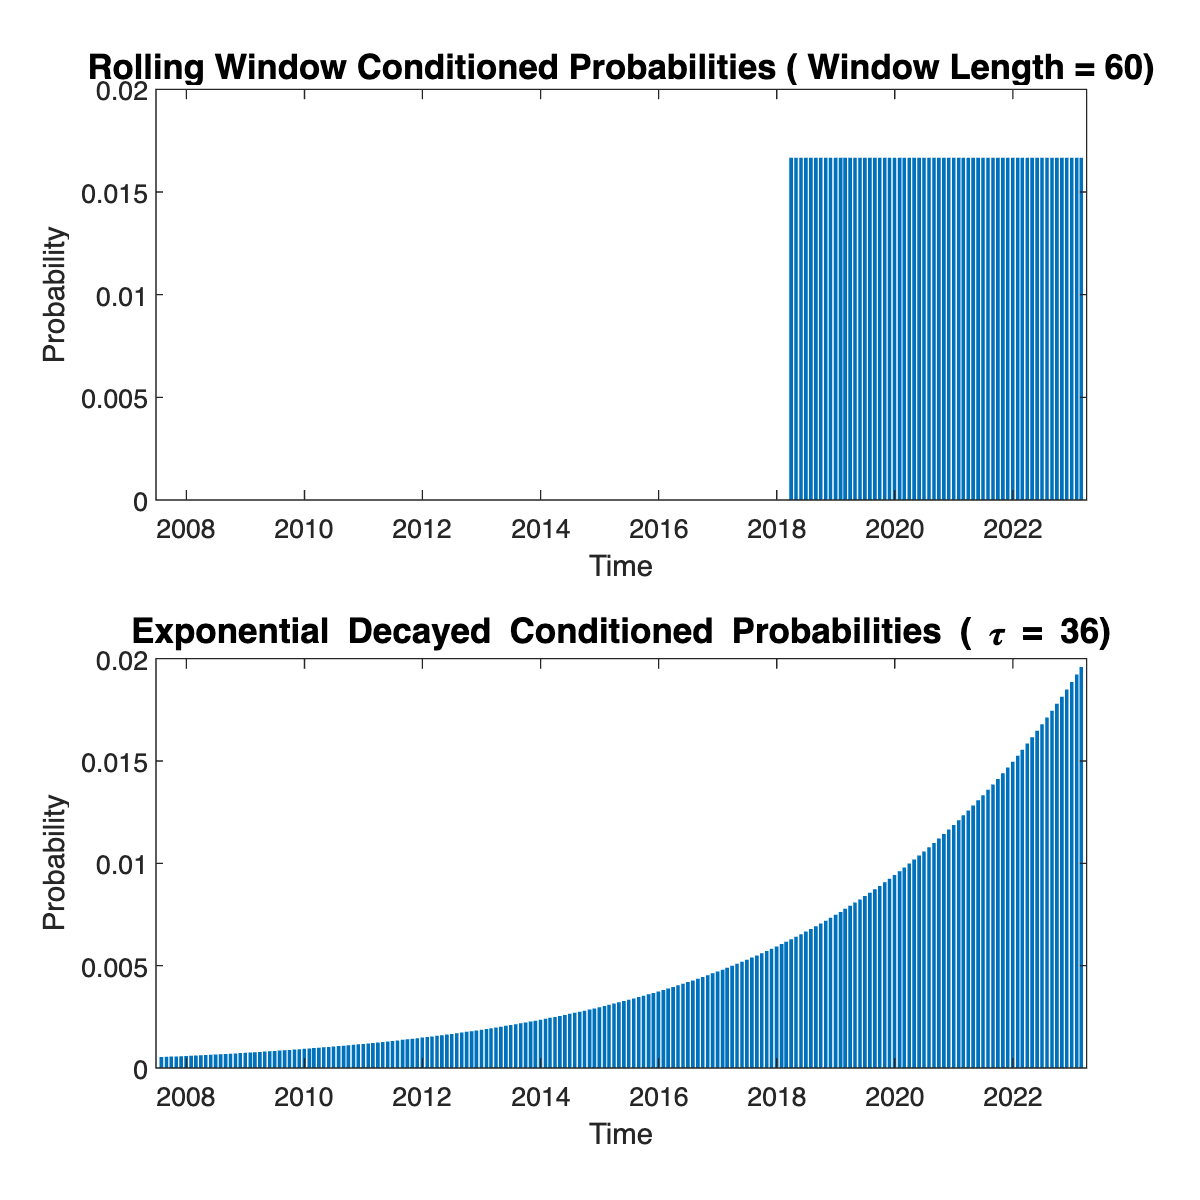

figure('OuterPosition', [100, 100, 600, 600]);
subplot(2,1,1);
HSFP_RW_plot = bar(ASSETCL_log_diff.Time, p_rw);
% set(gca, 'YScale', 'log')
ylabel("Probability");
xlabel("Time");
title(['Rolling Window Conditioned Probabilities ( Window Length = ' num2str(Window_len) ')'],'FontSize', 13);

subplot(2,1,2)
HSFP_ES_plot = bar(ASSETCL_log_diff.Time, p_es);
% set(gca, 'YScale', 'log')
ylabel("Probability");
xlabel("Time");
title(['Exponential Decayed Conditioned Probabilities ( \tau = ' num2str(tau) ')'],'FontSize', 13);

HSFP_TIME_CON_plot = gcf;

**Export Rolling Window Pr plot**

exportName = 'HSFP_TIME_CON_plot.pdf';
exportgraphics(HSFP_TIME_CON_plot,fullfile(imageExportpath,exportName),'Resolution',300);

## 4. GENERAL INPUT SETUP: HSFP State-Conditioned Prs 

Use CPI as test 

alpha = 0.1; % Ann uses 0.1
gamma = 2;
h = 0.5;
Signal_series_CPI = SIG_SMOOTHED_TT.lagged_SACPIYOY_Index;
z_target_UQ = 1.9;
z_target = -0.9;
z_target_LQ = -1.4;

### 4.1 Using Single Var: Crisp Prs

[p_cr_UQ, z_ub_UQ, z_lb_UQ, z_max_UQ,z_min_UQ] = cr_probs(Signal_series_CPI, alpha, z_target_UQ);
[p_cr, z_ub, z_lb, z_max,z_min] = cr_probs(Signal_series_CPI, alpha, z_target);
[p_cr_LQ, z_ub_LQ, z_lb_LQ, z_max_LQ,z_min_LQ] = cr_probs(Signal_series_CPI, alpha, z_target_LQ);

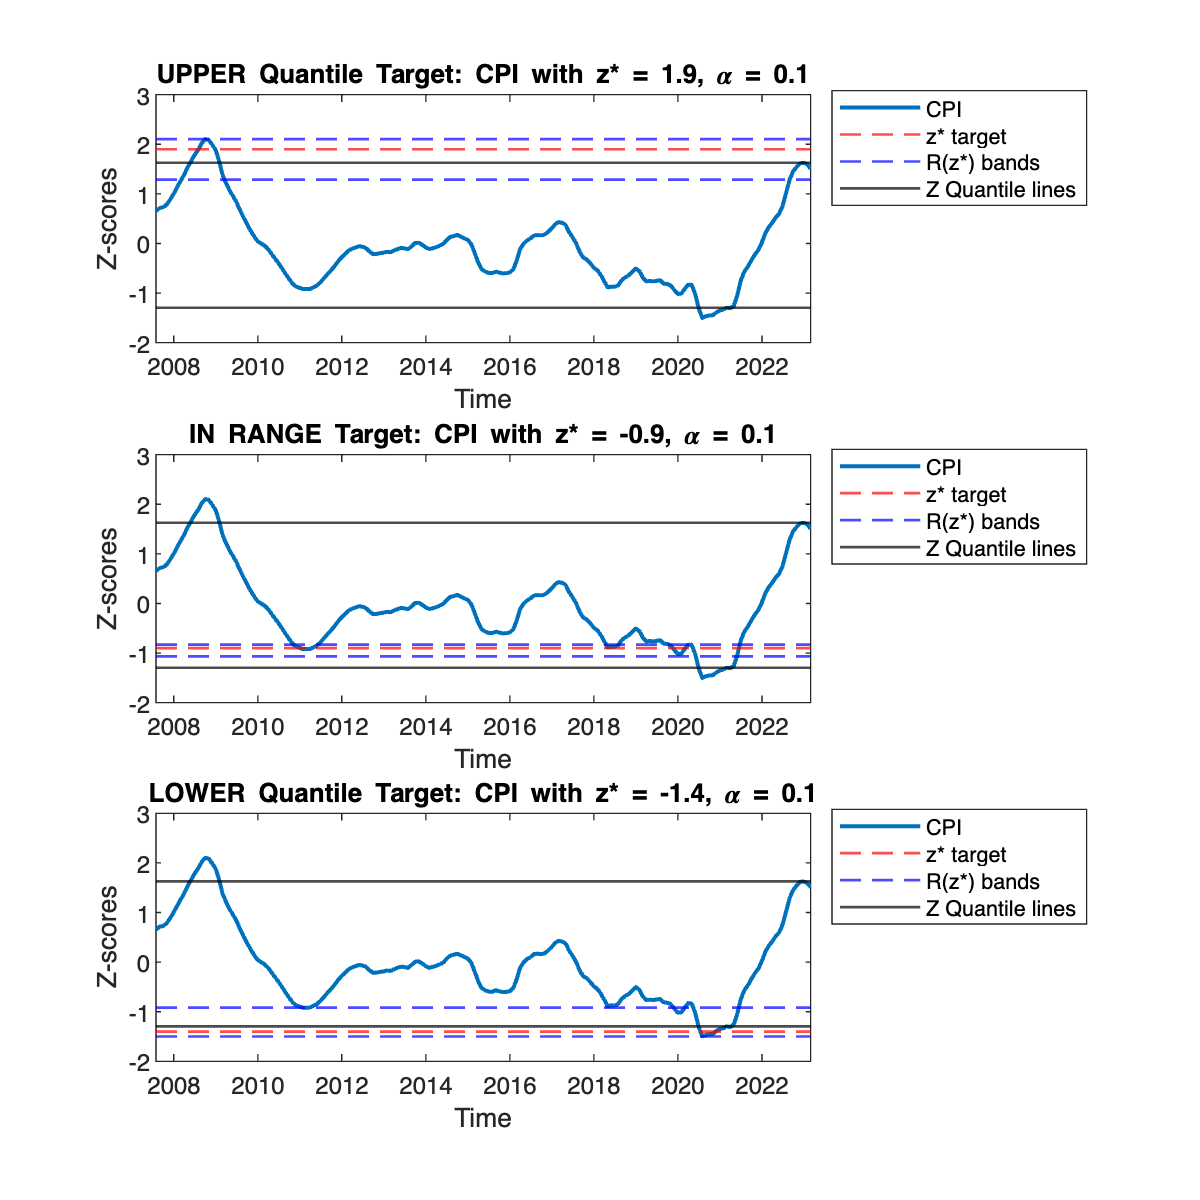

figure('InnerPosition', [100, 100, 600, 600]);
subplot(3,1,1);
plot(SIG_SMOOTHED_TT.Time, Signal_series_CPI, 'LineWidth', 1.5);
hold on;
yline(z_target_UQ, 'r--', 'LineWidth', 1);
yline(z_ub_UQ, 'b--', 'LineWidth', 1);
yline(z_max_UQ, 'black', 'LineWidth', 1);
yline(z_lb_UQ, 'b--', 'LineWidth', 1);
yline(z_min_UQ, 'black', 'LineWidth', 1);
hold off;
ylabel("Z-scores");
xlabel("Time");
legend('CPI', 'z* target', 'R(z*) bands', 'Z Quantile lines', 'Location', 'northeastoutside');

title(['UPPER Quantile Target: CPI with z* = ' num2str(z_target_UQ) ', \alpha = ' num2str(alpha) ]);

subplot(3,1,2);
plot(SIG_SMOOTHED_TT.Time, Signal_series_CPI, 'LineWidth', 1.5);
hold on;
yline(z_target, 'r--', 'LineWidth', 1);
yline(z_ub, 'b--', 'LineWidth', 1);
yline(z_max, 'black', 'LineWidth', 1);
yline(z_lb, 'b--', 'LineWidth', 1);
yline(z_min, 'black', 'LineWidth', 1);
hold off;
ylabel("Z-scores");
xlabel("Time");
legend('CPI', 'z* target', 'R(z*) bands', 'Z Quantile lines', 'Location', 'northeastoutside');

title(['IN RANGE Target: CPI with z* = ' num2str(z_target) ', \alpha = ' num2str(alpha) ]);

subplot(3,1,3);
plot(SIG_SMOOTHED_TT.Time, Signal_series_CPI, 'LineWidth', 1.5);
hold on;
yline(z_target_LQ, 'r--', 'LineWidth', 1);
yline(z_ub_LQ, 'b--', 'LineWidth', 1);
yline(z_max_LQ, 'black', 'LineWidth', 1);
yline(z_lb_LQ, 'b--', 'LineWidth', 1);
yline(z_min_LQ, 'black', 'LineWidth', 1);
hold off;
ylabel("Z-scores");
xlabel("Time");
legend('CPI', 'z* target', 'R(z*) bands', 'Z Quantile lines', 'Location', 'northeastoutside');
title(['LOWER Quantile Target: CPI with z* = ' num2str(z_target_LQ) ', \alpha = ' num2str(alpha) ]);

HSFP_CRISP_Quantile_Ranges_plot = gcf;
hold off;

#### **4.1.2 Export HSFP_CRISP_Quantile_Ranges_plot**

exportName = 'HSFP_CRISP_Quantile_Ranges_plot.pdf';
exportgraphics(HSFP_CRISP_Quantile_Ranges_plot,fullfile(imageExportpath,exportName),'Resolution',300);

% %%%%%%% UPPER QUANTILE TARGET CRISP PLOT %%%%%%%%
% figure('OuterPosition', [100, 100, 600, 600]);
% subplot(3,1,1);
% plot(SIG_SMOOTHED_TT.Time, Signal_series_CPI, 'LineWidth', 1.5);
% hold on;
% yline(z_target_UQ, 'r--',LineWidth= 1);
% yline(z_ub_UQ, 'b--',LineWidth= 1);
% yline(z_max_UQ, 'black',LineWidth= 1);
% yline(z_lb_UQ, 'b--',LineWidth= 1);
% yline(z_min_UQ, 'black',LineWidth= 1);
% hold off;
% ylabel("Z-scores");
% xlabel("Time");
% legend('CPI', 'z* target','crisp upper band','Z upper quantile line','crisp lower band','Z lower quantile line', 'Location', 'northeastoutside');
% title(['UPPER Quantile Target: CPI with z* = ' num2str(z_target_UQ) ', \alpha = ' num2str(alpha) ]);
% 
% 
% %%%%%%% INRANGE TARGET CRISP PLOT %%%%%%%%
% subplot(3,1,2);
% plot(SIG_SMOOTHED_TT.Time, Signal_series_CPI, 'LineWidth', 1.5);
% hold on;
% yline(z_target, 'r--',LineWidth= 1);
% yline(z_ub, 'b--',LineWidth= 1);
% yline(z_max, 'black',LineWidth= 1);
% yline(z_lb, 'b--',LineWidth= 1);
% yline(z_min, 'black',LineWidth= 1);
% hold off;
% ylabel("Z-scores");
% xlabel("Time");
% legend('CPI', 'z* target','crisp upper band','Z upper quantile line','crisp lower band','Z lower quantile line', 'Location', 'northeastoutside');
% title([' IN RANGE Target: CPI with z* = ' num2str(z_target) ', \alpha = ' num2str(alpha) ]);
% %%%%%%% LOWER QUANTILE TARGET CRISP PLOT %%%%%%%%
% subplot(3,1,3);
% plot(SIG_SMOOTHED_TT.Time, Signal_series_CPI, 'LineWidth', 1.5);
% hold on;
% yline(z_target_LQ, 'r--',LineWidth= 1);
% yline(z_ub_LQ, 'b--',LineWidth= 1);
% yline(z_max_LQ, 'black',LineWidth= 1);
% yline(z_lb_LQ, 'b--',LineWidth= 1);
% yline(z_min_LQ, 'black',LineWidth= 1);
% hold off;
% ylabel("Z-scores");
% xlabel("Time");
% legend('CPI', 'z* target','crisp upper band','Z upper quantile line','crisp lower band','Z lower quantile line', 'Location', 'northeastoutside');
% title(['LOWER Quantile Target: CPI with z* = ' num2str(z_target_LQ) ', \alpha = ' num2str(alpha) ]);

### 4.2  Using Single Var: Kernel Prs

knl_check_prs = kl_probs(Signal_series_CPI, h , gamma , z_target);
sum(knl_check_prs);

bar(knl_check_prs);

## 5. HSFP Time- & State-Conditioned Prs

### 5. 1 Entropy Pooling

Select a suitable prior. Here we use the exponential decay prior as this conditions by time before we condition by state using crisp condition.

**Check NB: tau_prior is set based on rebalancing frequency**

tau_prior = 3*12; % Ann did 5 yrs
% EPool_prior = es_probs(SIG_SMOOTHED_TT, tau_prior);
% bar(EPool_prior)

% Use exponential smoothing as prior
post_pr_CPI = ep_probs(Signal_series_CPI, alpha,tau_prior,z_target);

plot(post_pr_CPI)

Plot Kernel if wanted

% HSFP_KERNEL_plot = bar(SIG_SMOOTHED_TT.Time, knl_check_prs);
% set(gca, 'YScale', 'log')
% % ylim([10^-4, 10^-1])
% ylabel("Probability");
% xlabel("Time");

Plot State & Time COnditioned comparison

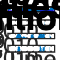

%%%%%%%  SIGNAL PLOT %%%%%%%%
figure('OuterPosition', [100, 100, 600, 600]);
subplot(4,1,1);
plot(SIG_SMOOTHED_TT.Time, Signal_series_CPI, 'LineWidth', 1.5);
% set(gca, 'YScale', 'log')
hold on;
yline(z_target, 'r--','Label', 'z*');
yline(z_ub, 'b--');
yline(z_max, 'black');
yline(z_lb, 'b--');
yline(z_min, 'black');
hold off;
ylabel("Z-scores");
xlabel("Time");
title(['Standardised CPI with z* & U/L Bound ( z* = ' num2str(z_target) ', \alpha = ' num2str(alpha) ')'],'FontSize', 13);


% close all (COMMENT OUT TO PLOT)
%%%%%%%  CRISP PLOT %%%%%%%%
subplot(4,1,2);
HSFP_CRISP_plot = bar(SIG_SMOOTHED_TT.Time, round(p_cr,2));
% set(gca, 'YScale', 'log')
%  ylim([10^-10, 1])
ylabel("Probability");
xlabel("Time");
title(['Crisp Conditioned Probabilities ( z* = ' num2str(z_target) ', \alpha = ' num2str(alpha) ')'],'FontSize', 13);


%%%%%%%  KERNEL PLOT %%%%%%%%
subplot(4,1,3);
HSFP_KERNEL_plot = bar(SIG_SMOOTHED_TT.Time, knl_check_prs);
% set(gca, 'YScale', 'log')
% ylim([10^-7, 1])
ylabel("Probability");
xlabel("Time");
title(['Kernel Conditioned Probabilities ( z* = ' num2str(z_target) ', h = ' num2str(h) ', \gamma = ' num2str(gamma) ')'],'FontSize', 13);
% Save the combined plot as an image file

%%%%%%%  ENTROPY POOL PLOT %%%%%%%%
subplot(4,1,4);
HSFP_EPOOL_plot = bar(SIG_SMOOTHED_TT.Time, post_pr_CPI);
set(gca, 'YScale', 'log')
ylim([10^-10, 1])
ylabel("Probability");
xlabel("Time");
title(['Entropy Pooling Time & State Conditioned Probabilities (z* = ' num2str(z_target) ', \alpha = ' num2str(alpha) ')'],'FontSize', 13);

% Save the combined plot as an image file
HSFP_STATE_COND_plot = gcf;

#### ** Export STATE CONDITIONED Plot**

exportName = 'HSFP_STATE_COND_plot.pdf';
exportgraphics(HSFP_STATE_COND_plot, ...
    fullfile(imageExportpath,exportName),'Resolution',300);

## 6. HSFP Time- & MULTIPLE State-Conditioned Prs

**Will use CPI & DLI (Domestic Leading Indicator):**

Signal_series_CPI already extracted.

Signal_series_DLI = SIG_SMOOTHED_TT.lagged_OEZAKLAP_Index;
% Current target set as 'latest' point
z_CPI_target = Signal_series_CPI(end);
z_DLI_target = Signal_series_DLI(end);
% Entropy pooling using z_target at time T
post_pr_CPI_T = ep_probs(Signal_series_CPI, alpha,tau_prior, z_CPI_target);
post_pr_DLI_T = ep_probs(Signal_series_DLI, alpha,tau_prior, z_DLI_target);

### 6.1 Equally weighted prs

#### 6.1.1 Only using CPI and DLI:

**Manual** calculation

num_singals = 2;
EW_prs_0 = ones(1, num_singals);
EW_prs = EW_prs_0/sum(EW_prs_0);

% Combine the 2:
[EW_CPI_DLI_pr] = EW_prs(1)*post_pr_CPI_T + EW_prs(2)*post_pr_DLI_T;

#### **6.1.2 Using function** for comparision and confirmation of results. 

CPI_DLI_TT = timetable(SIG_SMOOTHED_TT.Time, ...
    SIG_SMOOTHED_TT.lagged_SACPIYOY_Index, ...
    SIG_SMOOTHED_TT.lagged_OEZAKLAP_Index);
[ew_CPI_DLI_ensemble] = ew_ensemble(CPI_DLI_TT, alpha, tau_prior , 'latest');

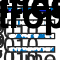

%%%%%%% CPI & DLI Combo ENTROPY POOL PLOT %%%%%%%%
HSFP_COMBO_EPOOL_plot = bar(SIG_SMOOTHED_TT.Time,  ew_CPI_DLI_ensemble);
set(gca, 'YScale', 'log')
ylim([10^-7, 1])
ylabel("Probability");
xlabel("Time");
title('CPI & DLI Equally Weighted Entropy Pooling Probabilities (z* = z_T)','FontSize', 13);

% Save the combined plot as an image file
HSFP_CPI_DLI_EW_plot = gcf;

#### **Export Plot EW Ensemble for CPI and Domestic Leading Indicator**

exportName = 'HSFP_CPI_DLI_EW_plot.pdf';
exportgraphics(HSFP_CPI_DLI_EW_plot, ...
    fullfile(imageExportpath,exportName),'Resolution',300);

#### 6.1.3 Ensemble EW of ALL singals

ew_ensemble(): Loop through all signals and calculate EPooled Prs for each then apply the EW Enseble approach

- Keep alpha and prior as used above.

% ew_pr_ensemble = ew_ensemble(SIG_SMOOTHED_TT, alpha, EPool_prior, 'latest');
% ens_EW_ensemble = ens(ew_pr_ensemble);

%%%%%%% ALL SIG EW Combo ENTROPY POOL PLOT %%%%%%%%
% EW_all_plot = bar(SIG_SMOOTHED_TT.Time, ew_pr_ensemble);
% % set(gca, 'YScale', 'log')
% % ylim([10^-4, 1])
% ylabel("Probability");
% xlabel("Time");
% title('EW All Signals Entropy Pooled Conditioned Ensemble Flexible Probabilities');

### 6.2 Conditioned Bayesian Ensemble (CBE) weighted prs

#### 6.2.1 Checking Effective Number of Scenarios (ENS)

We first check **Effective Number of Scenarios** when:

- p = 1/t we have DCC minimized and ENS is maximal at J = t --> this exploits all information 

- p = 1 for a single scenario then DCC is maximized and ENS is minimal at J = 1 -->

% Probability for equally weighted scenarios
p_ew = ones(1, height(SIG_SMOOTHED_TT));
p_ew = p_ew/sum(p_ew);
% Probability for a single scenario case
p_single_sig = zeros(1,height(SIG_SMOOTHED_TT));
p_single_sig(1) = 1;

ens_ew = ens(p_ew); % result: 188, therefore maximum at J = T
ens_single_sig = ens(p_single_sig); % result: 1, therefore minimum at J = 1

Compare with a 'middle ground Pr'

#### 6.2.2 Applying to 2 singals: CPI & DLI

- ENS for each signal

- Bhattacharyya coefficient

- Hellinger Distance

- Diversity Index (DCC)

- Weight based on ENS & DCC

[cb_CPI_DLI_ensemble, CPI_DLI_wts, CPI_DLI_ens_vals] = cb_ensemble(CPI_DLI_TT, alpha, tau_prior, 'latest','log-linear');

ens_CB_ENSEMBLE = 16.2201

ens_EW_ENSEMBLE = 4.5690

% post_pr_CPI_AnnTarget = ep_probs(Signal_series_CPI, 0.3, -1.04, EPool_prior);

% ens_CPI_EPool = ens(post_pr_CPI_AnnTarget)
ens_CB_ENSEMBLE = ens(EW_CPI_DLI_pr)
ens_EW_ENSEMBLE = ens(cb_CPI_DLI_ensemble) % result: confirms middle ground ENS.

#### 6.2.3 Applying to 2 singals: CPI & DLI

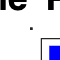

figure('OuterPosition', [100, 100, 600, 600]);

EW_plot = bar(SIG_SMOOTHED_TT.Time, ew_CPI_DLI_ensemble,'FaceColor','b');
set(gca, 'YScale', 'log')
ylim([10^-7, 1])
ylabel("Probability");
xlabel("Time");
title('Comparison of Ensemble Flexible Probability Distributions (z* = z_T)','FontSize', 13);
hold on;

CB_plot = bar(SIG_SMOOTHED_TT.Time, cb_CPI_DLI_ensemble,'facecolor', [0.3010 0.7450 0.9330]);
set(gca, 'YScale', 'log')
ylabel("Probability");

ylim([10^-7, 1])
xlabel("Time");
hold off;
% Add legend
legend('Equally Weighted Ensemble','Conditioned Bayesian Ensemble', 'Location','northwest');

HSFP_MULTISTATE_COMPARISON_plot = gcf;

exportName = 'HSFP_MULTISTATE_COMPARISON_plot.pdf';
exportgraphics(HSFP_MULTISTATE_COMPARISON_plot, ...
    fullfile(imageExportpath,exportName),'Resolution',300);

### 6.3 Individual EPool plots for CPI and DLI and compariosn with EW Ensemble and CB Ensemble

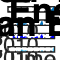

figure('OuterPosition', [100, 100, 600, 600]);
%%%%%%% CPI ENTROPY POOL PLOT %%%%%%%%
subplot(4,1,1);
HSFP_CPI_EPOOL_plot = bar(SIG_SMOOTHED_TT.Time, post_pr_CPI_T);
set(gca, 'YScale', 'log')
ylim([10^-7, 1])
% hold on;
% plot(SIG_SMOOTHED_TT.Time, Signal_series_CPI, 'LineWidth', 1.5);
% % yline(z_CPI_target, 'r--','Label', 'z*');
% hold off;(z* = z_T)','FontSize', 13
ylabel("Probability");
xlabel("Time");
title(['CPI Entropy Pooling Conditioned Probabilities (z* = z_T , ', '\alpha = ' num2str(alpha) ')'],'FontSize', 13);


%%%%%%% GDP ENTROPY POOL PLOT %%%%%%%%
subplot(4,1,2);
HSFP_GDP_EPOOL_plot = bar(SIG_SMOOTHED_TT.Time, post_pr_DLI_T);
set(gca, 'YScale', 'log')
ylim([10^-7, 1])
ylabel("Probability");
xlabel("Time");
title(['DLI Entropy Pooling Conditioned Probabilities (z* = z_T , ', '\alpha = ' num2str(alpha) ')'],'FontSize', 13);

%%%%%%% EQUALLY WEIGHTED CPI & DLI Combo ENTROPY POOL PLOT %%%%%%%%
subplot(4,1,3);
HSFP_EW_CPI_GDP_EPOOL_plot = bar(SIG_SMOOTHED_TT.Time, EW_CPI_DLI_pr,'FaceColor','b');
set(gca, 'YScale', 'log')
ylim([10^-7, 1])
ylabel("Probability");
xlabel("Time");
title('Equally Weighted Ensemble: CPI & DLI','FontSize', 13);

%%%%%%% CPI & DLI Combo ENTROPY POOL PLOT %%%%%%%%
subplot(4,1,4);
HSFP_CB_CPI_GDP_EPOOL_plot = bar(SIG_SMOOTHED_TT.Time, cb_CPI_DLI_ensemble,'facecolor', [0.3010 0.7450 0.9330]);

set(gca, 'YScale', 'log')
ylim([10^-7, 1])
ylabel("Probability");
xlabel("Time");
title('Conditioned Bayesian Ensemble: CPI & DLI','FontSize', 13);
HSFP_CPI_DLI_EP_and_ENSEMBLE_plot = gcf;

exportName = 'HSFP_CPI_DLI_EP_and_ENSEMBLE_plot.pdf';
exportgraphics(HSFP_CPI_DLI_EP_and_ENSEMBLE_plot, ...
    fullfile(imageExportpath,exportName),'Resolution',300);

## 7. Estimate Mu and Sigma of assets given FPs

returns_TT = ASSETCL_log_diff;
% [test_mu,test_sigma] = hsfp_moments(p_cr, returns_TT);

# 8. Testing sub-function to HSFP adjusted backtest

Pr Calculation checks using backtest_moments:

Rolling window works 

Exp Decay works

Crisp works

Kernel works

EPool works

EW_ensemble works

cb_ensemble works

Mean & Var calc check

% Options: and required parameters

%            - none (default) 

%            - rolling_w    (window)

%            - exp_decay    (tau)

%            - crisp        (alpha, z_target)

%            - kernel       (h, gamma, z_target)

%            - e_pooling    (alpha, tau_prior, z_target)

%            - ew_ensemble  (alpha, tau_prior, z_target)

%            - cb_ensemble  (alpha, tau_prior, z_target,ensemble_wt_method)

% Window_len = 12;
% tau = 12;
% alpha = 0.1;
% z_target = 'latest';
% h = 0.5;
% gamma = 2;
% tau_prior = 3*12; % Ann did 5 yrs
% ensemble_wt_method = 'log-linear';
% 
% % this currently set up to test cb_ensemble for backtest_moments.m function
% hsfp_parameters = struct('window',[],'tau',[],'alpha',[],'z_target',[], ...
%     'gamma',[],'h',[], 'EPool_prior',[], 'z_target_method',[],'ensemble_wt_method',[]);
% 
% hsfp_parameters.window = Window_len;
% hsfp_parameters.tau = tau;
% hsfp_parameters.alpha = alpha;
% hsfp_parameters.z_target = z_target;
% hsfp_parameters.h = h;
% hsfp_parameters.gamma = gamma;
% hsfp_parameters.tau_prior = tau_prior;
% hsfp_parameters.ensemble_wt_method = 'log-linear';
% 
% backtest_object = struct('returns',[],'signals',[],'method',[], 'parameters',[]);
% backtest_object.returns = returns_TT;
% backtest_object.signals = timetable(SIG_SMOOTHED_TT.Time, SIG_SMOOTHED_TT.lagged_SACPIYOY_Index,SIG_SMOOTHED_TT.lagged_OEZAKLAP_Index);
% % backtest_object.signals = SIG_SMOOTHED_TT.lagged_SACPIYOY_Index; % NB: needs to be a timetable object
% backtest_object.method = 'cb_ensemble';
% backtest_object.parameters = hsfp_parameters;

Window_len = 12;
tau = 12;
alpha = 0.1;
z_target = 'latest';
h = 0.5;
gamma = 2;
tau_prior = 1*12; % Ann did 5 yrs
ensemble_wt_method = 'log-linear';

% this currently set up to test cb_ensemble for backtest_moments.m function
hsfp_parameters = struct('window',[],'tau',[],'alpha',[],'z_target',[], ...
    'gamma',[],'h',[], 'tau_prior',[],'ensemble_wt_method',[]);

hsfp_parameters.window = Window_len;
hsfp_parameters.tau = tau;
hsfp_parameters.alpha = alpha;
hsfp_parameters.z_target = z_target;
hsfp_parameters.h = h;
hsfp_parameters.gamma = gamma;
hsfp_parameters.tau_prior = tau_prior;
hsfp_parameters.ensemble_wt_method = 'log-linear';

backtest_object = struct('returns',[],'Wts_lb',[],'Wts_ub',[],'signals',[],'method',[], 'parameters',[]);
% Returns Timetable
backtest_object.returns = returns_TT;
% Control bounds: lower and upper bounds for asset weights 
% backtest_object.Wts_lb = [ 0 0 0 0 0 ]; 
% backtest_object.Wts_ub = [ 1 1 1 1 0.05];
% Ensemble needs more than 1 signal series
backtest_object.signals = timetable(SIG_SMOOTHED_TT.Time, SIG_SMOOTHED_TT.lagged_SACPIYOY_Index);

hsfp_mu =     0.0053   -0.0054    0.0078   -0.0025    0.0071


hsfp_cov =     0.0006    0.0010    0.0006   -0.0001   -0.0005
    0.0010    0.0059    0.0032    0.0024   -0.0021
    0.0006    0.0032    0.0044    0.0031   -0.0016
   -0.0001    0.0024    0.0031    0.0093   -0.0016
   -0.0005   -0.0021   -0.0016   -0.0016    0.0028


p =     0.0091    0.0110    0.0115    0.0135    0.0178    0.0232    0.0295    0.0343    0.0377    0.0389    0.0371    0.0334    0.0292    0.0230    0.0192    0.0198    0.0244    0.0293    0.0373    0.0377    0.0327    0.0265    0.0209    0.0155    0.0094    0.0055    0.0031    0.0017    0.0009    0.0005    0.0004    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


% backtest_object.signals = SIG_SMOOTHED_TT.lagged_SAMYM3Y_Index; 
backtest_object.method = 'kernel';
backtest_object.parameters = hsfp_parameters;

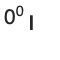

[hsfp_mu, hsfp_cov,p] = backtest_moments(backtest_object)

HSFP_EPOOL_plot = bar(SIG_SMOOTHED_TT.Time, p);
set(gca, 'YScale', 'log')
ylim([10^-7, 1])
ylabel("Probability");

#### **USE the below to check the effect of HSFP vs normal mean.**

% conventional mean
mean(table2array(returns_TT));
% HSFP EPool means with negative target value
hsfp_mu;
mean(SIG_SMOOTHED_TT.lagged_SACPIYOY_Index);
% hsfp_mu-mean(table2array(returns_TT));

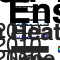

% correlation of inflation to the return classes
returns_TT.CPI = SIG_SMOOTHED_TT.lagged_SACPIYOY_Index;
% rename the variables with underscores instead of spaces
Asset_Names = returns_TT.Properties.VariableNames;
ASSETCL_PlotNames = strrep(Asset_Names, '_', ' ');
% remove the 'TR' the variables with underscores instead of spaces
ASSETCL_PlotNames = strrep(ASSETCL_PlotNames, 'TR', '');

CPI_asset_cor = round(corr(table2array(returns_TT)),2);
% h = heatmap(BALFUN_PlotNames,BALFUN_PlotNames,AssetCorr, 'Colormap',winter());
% Plot the heatmap with a sliding range of colors
heatmap_CPI_ASSETS = heatmap(ASSETCL_PlotNames, ASSETCL_PlotNames, CPI_asset_cor, 'Colormap', jet(6));
heatmap_CPI_ASSETS.Title = 'Pairwise Pearson Correlation Heatmap for CPI & Asset Classes';

% exportName = 'HSFP_CPI_DLI_EP_and_ENSEMBLE_plot.pdf';
exportName = 'CPI_ASSET_corr_heatmap.pdf';
exportgraphics(heatmap_CPI_ASSETS, ...
    fullfile(imageExportpath,exportName),'Resolution',300);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%